# `JPEG Compression`

# `An Information Theory Project`

`Abdelrahman Elaraby`

`s-abdelrahman_elaraby@zewailcity.edu.eg`

#### `Sections:`

- `What is JPEG? why?`

- `Steps of the JPEG compression and decompression`

- `My implemented functions`

- `JPEG Encoder, testing and coding flow`

- `JPEG Decoder, testing and coding flow`

## `What is JPEG? why?`

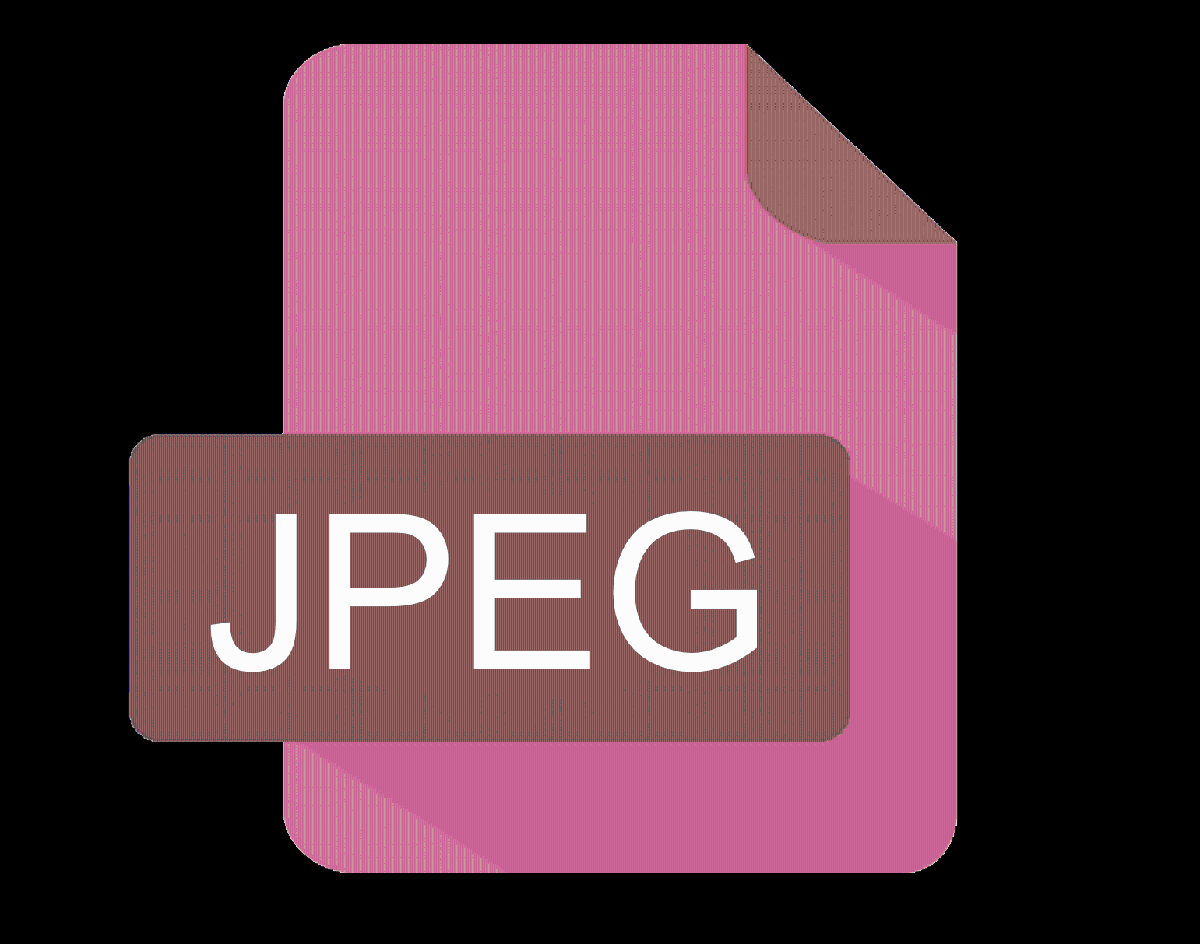

`JPEG is a digital compression method for images. The amount of compression can be changed by setting some parameters in the algorithm. In the compression process, there is a tradeoff between image qualitiy and compression ratio. `

`Why we do compression? to make good use of the limited storage space, or the limitied bandwidth in transmission.`

## `Steps of the JPEG compression and decompression`

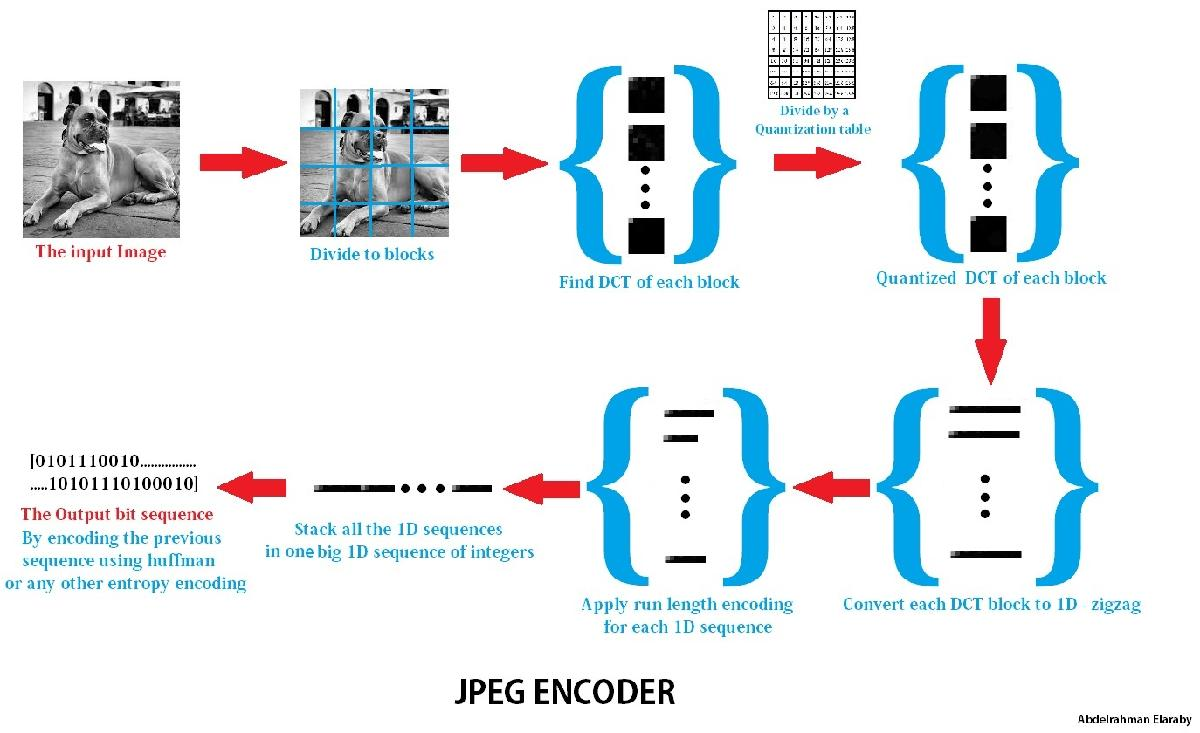

AS shown above, the JPEG compression is done in these steps, A lossy compression comes from the quantization table, and a lossless compression comes from both the runlength and huffman encoding.

The Idea of Discrete Cosine Transform (DCT) here is converting the image from the intensity domain to a more ***sparse*** domain where we can find alot of zeros and the values are concentrated in a tiny portion of the domain's space.

So, The encoding steps are:

- Dividing the image to blocks. you can change "block size"  parameter.

- Finding the DCT of each block.

- Dividing by the Quantization table.

- Converting each 2D DCT block to 1D vector.

- Apply run length encoding to reduce redundancy.

- stack the 1D sequences and apply a lossless entropy coding like Huffman. 

Now you ended up with a compressed image (i.e. the image is represented in an effiecient way instead of assigning 8 bits to each pixel for example), you can save or transmit the image or do whatever you want now more efficiently.

The Decoding steps are just the reverse of the Encoder:

- Decode the bits sequence "huffman decoder".

- Apply run length decoder.

- Divide the resulted sequence into equally lengthed 1D sequences, and then convert to 2D.

- Multiply each block by the Quantization table.

- Finding the IDCT of each block.

- Combine these small 2D blocks to form one 2D image.

## `My implemented functions:`

`Note that you can find the documentation of each function inside it file, this sectionis just explaining the inputs and outputs of each module.`

#### `#1 [blocks] = DivideToBlocks(img,bSize);`

    `where input:`

`    img`` (2D-double),is a 2D image.`

`    bSize ``(double),is the block length(or width) to divide the image with.`

    `while the output:`

`    blocks`` (4D-double),is a 4D array containing the blocks of the image.`

#### `#2 [img] = CombineBlocks(blocks);`

    `where input:`

`    blocks`` (4D-double),is a 4D array containing the blocks of the image.`

    `while the output:`

`    img`` (2D-double),is a 2D image.` 

#### `#3 [blocksDCT] = DCT_Blocks(blocks);`

    `where input:`

`    blocks`` (4D-double),is a 4D array containing the blocks of the image.`

    `while the output:`

`    blocksDCT ``(4D-double),is a 4D array containing the corresponding DCT of each block.`

    `this function uses internally the following function`

#### `#4 [blockDCT] = DCT_2D(block);`

    `where input:`

`    block`` (2D-double),is one of the small 2D blocks of the image.`

    `while the output:`

`    blockDCT ``(2D-double),is the 2D corresponding DCT of the block.`

#### `#5 ``[blocks] = IDCT_Blocks(blocksDCT)``;`

    `where input:`

    `blocksDCT ``(4D-double),is a 4D array containing the corresponding DCT of each block.`

    `while the output:`

`    blocks`` (4D-double),is a 4D array containing the restored blocks of the image.`  

    `this function uses internally the following function`

#### `#6 ``[block] = IDCT_2D(blockDCT)``;`

    `where input:`

`    blockDCT ``(2D-double),is the 2D DCT of a block.`

    `while the output:`

`    block`` (2D-double),is a restored small 2D block of the image.`

#### `#7 ``[Q_blocksDCT] = Quantization(blocksDCT,table_n,Qtable)``;`

    `where input:`

    `blocksDCT ``(4D-double),is a 4D array containing the corresponding DCT of each block.`

    `table_n`` (double),set "1 or 2 for using table_1 or table_2", or "-1 for using Qtable".`

    `Qtable ``(2D-double),is your defined quantization table, set table_n = -1 to use it.`

    `while the output:`

`    Q_blocksDCT`` (4D-double),is the quantized blocksDCT. `

#### `#8 ``[blocksDCT] = DeQuantization(Q_blocksDCT,table_n,Qtable)``;`

    `where input:`

`    Q_blocksDCT`` (4D-double),is the quantized blocksDCT.`

    `table_n`` (double),set "1 or 2 for using table_1 or table_2", or "-1 for using Qtable".`

    `Qtable ``(2D-double),is your defined quantization table, set table_n = -1 to use it.`

    `while the output:`

    `blocksDCT ``(4D-double),is a 4D array containing the corresponding DCT of each block.`

#### `#9 ``[block_1D] = Convert_1D_zigzag(block)``;`

    `where input:`

`    block ``(2D-double),is a 2D block.`

    `while the output:`

`    block_1D`` (1D-double),is a 1D zig-zag transform of the input block.`

#### `#10 ``[block] = Convert_2D_zigzag(block_1D)``;`

    `where input:`

`    block_1D`` (1D-double),is a 1D zig-zag transform of the input block.`

    `while the output:`

`    block ``(2D-double),is a 2D block.`

#### `#11 ``[runLengthSequence] = RunLengthEncoder(block_1D)``;`

    `where input:`

`    block_1D`` (1D-double),is a 1D sequence of integers.`

    `while the output: `

`    runLengthSequence ``(1D-double),is the shortened sequence after encoding.`

#### `#12 ``[``block_1D``] = RunLengthDecoder(runLengthSequence)``;`

    `where input:`

`    runLengthSequence ``(1D-double),is the shortened sequence after run length encoding.`

    `while the output:`

`    block_1D`` (1D-double),is a 1D sequence of integers.`

#### `#13 ``[code,dict] = HuffmanEncoder(sequence)``;`

    `where input:`

`    sequence ``(1D-double),is a 1D sequence of integers. `

    `while the output:`

`    code`` (2D-double),is a 1D sequence of bits, the encoding of the input. `

`    dict`` (2D-cell),is the list mapping each integer to its assigned code. `

## `JPEG Encoder, testing and coding flow`

`I will illustrate the work flow on an image after converting it to grayscale image for simplicity.`

`The image I choose is an 180*180 pixels, you can enter the path to any image you want; But the larger the image, the slower the compression process.`

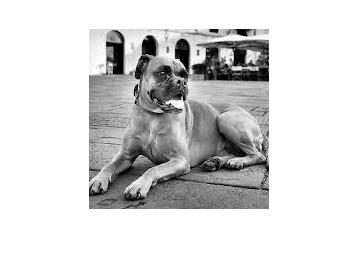

image = imread('.\dog.jpg'); %reading the Image file
imshow(image);

To do the compression, there are parameters affecting the final output, and you need to choose these parameters to meet the specifications you want (image quality and compression ratio). The parameters here are the "Quantization table" and the "block size". By inspection, I found that to reach an image quality of ***"MSE less than 35"*** and ***"compression ratio of 1:2.5" ***or more I will go for quantization table_1 provided inside my implemented quantization function (and shown below), and a block size of 8x8 pixel. To set these settings, I will define the two variables bSize and table_n.

If you want to choose your own Quantization table, change the values of the variable Qtable below, and set table_n = -1. make sure that your Qtable is of size [bSize x bSize].

%settings of the JPEG
bSize = 8; %choosing the block size that will be used in compression
table_n = 1; %to choose the table you want
%you can set table_n = 1 for table_1, 2 for table_2, -1 for Qtable.
%table_1 = [1 1 1 1 1 2 2  4;
%           1 1 1 1 1 2 2  4;
%           1 1 1 1 2 2 2  4;
%           1 1 1 1 2 2 4  8;
%           1 1 2 2 2 2 4  8;
%           2 2 2 2 2 4 8  8;
%           2 2 2 4 4 8 8  16;
%           4 4 4 4 8 8 16 16];
%table_2 = [1 2 4 8 16 32 64 128;
%           2 4 4 8 16 32 64 128;
%           4 4 8 16 32 64 128 128;
%           8 8 16 32 64 128 128 256;
%           16 16 32 64 128 128 256 256;
%           32 32 64 128 128 256 256 256;
%           64 64 128 128 256 256 256 256;
%           128 128 128 256 256 256 256 256];
%your Quantization table.
Qtable = [1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          1 1 1 1 1 2 2 4 4 4 4 4 4 4 4;
          2 2 2 2 2 2 2 4 4 4 4 4 4 4 4;
          2 2 2 2 2 2 2 4 4 4 4 4 4 4 4;
          4 4 4 4 4 4 4 4 4 4 4 4 4 4 4;
          4 4 4 4 4 4 4 4 4 4 4 4 4 4 4;
          4 4 4 4 4 4 4 4 4 4 4 4 4 4 4;
          4 4 4 4 4 4 4 4 4 4 4 4 4 4 16;
          4 4 4 4 4 4 4 4 4 4 4 4 4 16 16
          4 4 4 4 4 4 4 4 4 4 4 4 16 16 16;];

As you can see from the illustraion figure shown at the beginning, the first step of JPEG is dividing the image into blocks of the choosen bSize. Note that there is a possibility that parts of the image will get trimmed if the image dimensions isn't divisible by bSize. The code below do the image division and shows a sample block of the image.

#### #1-Dividing the image:

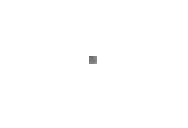

blocks = DivideToBlocks(image,bSize);%Divide the image to blocks and store them in 4D array
[~,~,xBlocks,yBlocks] = size(blocks); %Getting the number of X and Y blocks 
block = blocks(:,:,12,10); %taking a certain block
imshow(uint8(block));

disp(block); %displaying the values of the pixels of the shown block above.

   103   102   109   113   127   130   137   144
   114   117   111   107   127   134   137   144
   125   125   116   111   125   132   136   141
   120   117   120   123   121   124   135   138
   115   114   115   122   121   124   134   133
   110   132   130   124   118   119   131   146
   128   140   124   123   131   137   140   146
   129   135   126   133   134   140   150   157



You can double check by openeing the figure of the block and see the intensity of each pixel and compare it to the values show above.

Next step is finding the DCT for each block of the image, the below code does that and shows the output on the same block illustrated in the previous step.

#### #2-Finding the DCT:

[blocksDCT] = DCT_Blocks(blocks); %Finding the DCT of each image block
disp(blocksDCT(:,:,12,10)); %displaying the values of the DCT of the shown block above.

  126.9688  -11.1870    4.9281   -1.0460   -0.4419   -1.7323   -1.0368   -0.0425
   -6.1477   -4.3461   -0.5354    2.8733    0.7130    0.0987    1.6521    1.8795
    3.1514   -3.9638    0.4268    1.4933    0.0577   -1.7457    0.0259   -0.0194
   -3.5140   -1.0112   -2.1105   -3.0178   -0.1470   -0.0560   -0.0414    0.1108
   -0.7955   -2.3129   -2.0770    0.0305    1.9375    3.2128    0.0485    0.0835
    0.5032    1.1096   -0.0416   -0.0024    0.0456   -0.0510    0.1028   -0.0094
   -0.0138    0.0843    0.1509   -2.5469   -0.0239   -0.0028    0.0732   -0.0200
   -0.0802    0.0581    0.0428    3.0245    0.0836    0.0279   -0.1175    0.0399



As you can see, there are many low values and zeros, most of values are condensated in the upper left corner. meaning that the images naturally contains low frequencies. Remember that the above 8x8 matrix show the correlation "DCT coefficients" between the image block and each of the 2D bases functions "cosines", for instance, the upper left corner is for the DC basis function, and it has the higher value.

We can make use of this sparsity, we can neglect these low values in the above shown coefficients or lower their resolution and still have a very good approximation to the original block after applying the inverse cosine transform (IDCT). How to do this neglection or lowering of the resolution? by the quantization tables. We simply divide each blockDCT by the table element wise.The code below is doing the quantization process and showing the effect on our illustrated block.

#### #3-Quantization:

[Q_DCTblocks] = Quantization(blocksDCT,table_n,Qtable); %Applyig a Quantization table
%table_1 = [1 1 1 1 1 2 2  4;
%           1 1 1 1 1 2 2  4;
%           1 1 1 1 2 2 2  4;
%           1 1 1 1 2 2 4  8;
%           1 1 2 2 2 2 4  8;
%           2 2 2 2 2 4 8  8;
%           2 2 2 4 4 8 8  16;
%           4 4 4 4 8 8 16 16];
disp(Q_DCTblocks(:,:,12,10)); %displaying the values of the Quantized output.

   126    -5     1     0     0     0     0     0
    -3    -1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



You can find clearly now lots of zeros, we are interested in these zeros following each other because we can apply a run length encoding and lower the redundancy and the needed space to save! But to apply run length encoding, we need to convert this 2D block to a 1D sequence, but we'll do this in a zig-zag way to make most of the zeros come after each others.

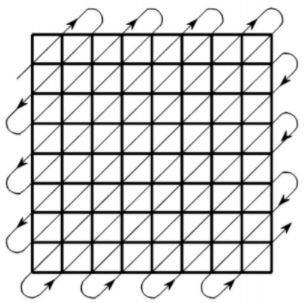

#### #4-Convert to 1D:

The below code is a test of applying the zig-zag on our illustrated block.

[block_1D] = Convert_1D_zigzag(Q_DCTblocks(:,:,12,10));%convert it to 1D using the zigzag way
disp(block_1D);

  Columns 1 through 20

   126    -5    -3     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 21 through 40

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 41 through 60

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 61 through 64

     0     0     0     0



After having 1D row vector, we can apply run length encoding to it, the code below does this.

#### #5-Run length encoding:

[runLengthSequence] = RunLengthEncoder(block_1D);
disp(runLengthSequence);

   126    -5    -3     0     1    -1     1     0    58



It is obvious now how much redundancy we removed. I will do the same process (converting to 1D then run length) on each block and then stacking all the shortened sequences together in one 1D sequence. The code below does this.

#### #6-Stack them, and do huffman:

stacked_1D_Sequences = []; %empty 1D array for storing the final sybmols
for i=1:xBlocks
    for j=1:yBlocks
        block = Q_DCTblocks(:,:,i,j); %taking a certain block
        [block_1D] = Convert_1D_zigzag(block);%convert it to 1D using the zigzag way
        %applying runlength encoding to lower the number of symbols if zeros repeated after each other.
        [runLengthSequence] = RunLengthEncoder(block_1D);
        %appending the block's 1D sequence to the big 1D sequence.
        stacked_1D_Sequences = [stacked_1D_Sequences runLengthSequence];
    end
end
disp(size(stacked_1D_Sequences));

           1        5953



Currently we have the image represented by 20826 symbols or integers, our original image had 176x176 = 30976 symbols (it was 180x180 but cropped to fit the block division). It is clear now that compression is taking a place!

The final remaining step is transforming these 20826 integers to bits. The efficient way is applying an entropy encoding that assigns the least number of bits to most frequent symbols, thus lowering the average length of the codewords. I will use Huffman encoding for that purpose.

% A function the uses matlab's builtin huffman encoder, returns the bits
% and the dictionary list to use it in decoding.
[encodedSeq,dict] = HuffmanEncoder(stacked_1D_Sequences);
%NOW YOU CAN SEND OR SAVE THE "encodedSeq", which is the compressed image.
disp(encodedSeq(1:10))%just printing a sample of the bits

     1     1     1     1     1     0     1     0     1     0



[~,numOfEncBits] = size(encodedSeq);
disp(numOfEncBits);

       29029



*NOW WE ARE DONE WITH JPEG ENCODING!*

The image is compressed and saved to 94911 bits. For reference, the original image had 30976 pixels or integers, if assigned fixed length codword of 8-bits per pixel, then the uncompressed image will have 247808 bits. you can find a code below for computing the compression ratio.

%Compression ratio calculations
uncompressedBits = (bSize^2)*xBlocks*yBlocks*8;
compRatio = (numOfEncBits/uncompressedBits)*100;
%In format (% of uncompressed(8-bits/pixel) used)
disp(string(compRatio)+"%");

11.7143%


%In format (encoded bits : uncompressed bits)
disp(string(1)+" : "+string(uncompressedBits/numOfEncBits));

1 : 8.5366


You can find that we've met the needed compression ratio, but we still need to know the image quality. To achieve that, we'll implement the *decoding steps*.

## `JPEG Decoder, testing and coding flow`

`The Decoder is basically the inverse flow of the encoder, lets start by the huffman decoder. and applying the runlength decoding.`

#### #1-Decode the huffman sequence:

decoded_stacked_1D_Sequences = huffmandeco(encodedSeq,dict); %Matlab's huffman decoder
disp(size(decoded_stacked_1D_Sequences));

           1        5953



disp(decoded_stacked_1D_Sequences(1:7))

   218     0    63   220     0     1    -1



You can see now that we have the same 20826 integers appeared earlier before the huffman encoding. Let's do the run length decoding below.

#### #2-Apply run length decoder:

%Restore all the symbols after reversing the runlength encoding applied 
[restoredStacked_1D] = RunLengthDecoder(decoded_stacked_1D_Sequences);
disp(restoredStacked_1D(1:10));

   218     0     0     0     0     0     0     0     0     0



The run length decoder worked successfully, compare the last 2 displayed outputs and you can see the sequence [0 6] converted to six zeros [0 0 0 0 0 0] and so is [0 1] to [0].

The Next step is slicing this long sequence ino equal length sequences, and converting each one of them to a 2D block.

#### #3-Dividing to equal 1D sequences and then to 2D:

%placeholder for the restored 2D blocks
restored_Q_blocksDCT = zeros(bSize,bSize,xBlocks,yBlocks);
index = 0; %will be used in looping over the 1D array
%loop over the 1D sequence, take each (bSize^2) integers and put them in 2D
for i=1:xBlocks
    for j=1:yBlocks
        indx = index*(bSize^2);
        %restore them in a 2D block.
        restored_Q_blocksDCT(:,:,i,j) = Convert_2D_zigzag(restoredStacked_1D(1,  indx+1: indx+(bSize^2)));
        index = index +1; %take the next (bSize^2) integers
    end
end
disp(restored_Q_blocksDCT(:,:,12,10));

   126    -5     1     0     0     0     0     0
    -3    -1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



That's the same block we illustrated earlier in the encoding process, we recieved it from the decoder successfully.

The coming step is revesing the Quantization, by multiplying each block with the chosen table.

#### #4-Apply the inverse of quantization:

%Reversing the Quantization done in the transmitter
[restored_blocksDCT] = DeQuantization(restored_Q_blocksDCT, table_n,Qtable);
disp(restored_blocksDCT(:,:,12,10));

   126   -10     4     0     0     0     0     0
    -6    -4     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



disp(blocksDCT(:,:,12,10));%that's the original DCT block before quantization at the encoder.

  126.9688  -11.1870    4.9281   -1.0460   -0.4419   -1.7323   -1.0368   -0.0425
   -6.1477   -4.3461   -0.5354    2.8733    0.7130    0.0987    1.6521    1.8795
    3.1514   -3.9638    0.4268    1.4933    0.0577   -1.7457    0.0259   -0.0194
   -3.5140   -1.0112   -2.1105   -3.0178   -0.1470   -0.0560   -0.0414    0.1108
   -0.7955   -2.3129   -2.0770    0.0305    1.9375    3.2128    0.0485    0.0835
    0.5032    1.1096   -0.0416   -0.0024    0.0456   -0.0510    0.1028   -0.0094
   -0.0138    0.0843    0.1509   -2.5469   -0.0239   -0.0028    0.0732   -0.0200
   -0.0802    0.0581    0.0428    3.0245    0.0836    0.0279   -0.1175    0.0399



Comparing the de-quantized block and the original one, it's obvious now what is meant by ***"lossy compression"***, we have no clue or method to restore the values that became zeros, or the lost resolution of values.

The remaining steps are just applying the IDCT to restore the blocks to the intensity domain again, and then combining these blocks in one 2D image.

#### #5-Finding the IDCT:

%Reversing the DCT done earlier (finding the IDCT of each block)
[restored_blocks] = IDCT_Blocks(restored_blocksDCT);
disp(uint8(restored_blocks(:,:,12,10)));

   110   110   111   114   119   126   133   137
   112   111   112   115   120   127   134   138
   114   114   114   117   121   128   134   138
   118   117   117   119   123   129   135   139
   122   121   121   122   125   131   136   140
   125   124   123   124   127   132   137   141
   128   127   126   126   129   133   138   141
   130   128   127   127   129   134   138   142



disp(blocks(:,:,12,10));%that's the original block.

   103   102   109   113   127   130   137   144
   114   117   111   107   127   134   137   144
   125   125   116   111   125   132   136   141
   120   117   120   123   121   124   135   138
   115   114   115   122   121   124   134   133
   110   132   130   124   118   119   131   146
   128   140   124   123   131   137   140   146
   129   135   126   133   134   140   150   157



sum(sum(uint8(blocks(:,:,12,10))-uint8(restored_blocks(:,:,12,10))))%finding the error betweem them.

ans = 197

As expected, due to the lossy compression (because of the quantization table), the restored block is slightly different than the original one, but here it's a good approximation.

Now let's look at the final restored image after combining the restored blocks.

#### #6-Combine the restored blocks to one image:

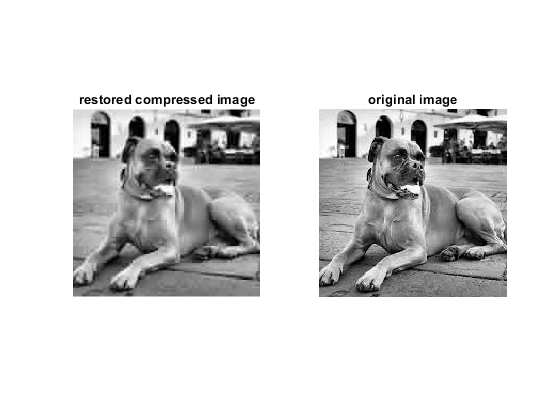

%Combine the small 2D blocks in one big 2D image.
[restored_image] = CombineBlocks(restored_blocks);
figure;
subplot(1,2,1);
imshow(uint8(restored_image));%restored compressed image
title("restored compressed image");
subplot(1,2,2);
imshow(image(1:xBlocks*bSize,1:yBlocks*bSize));%original image
title("original image");

Not Much of a difference seen by the eye, but let's calculated the Mean Squared Error over all the blocks between the original and restored image after the compression, and that's the image quality.

%converting the original image to double. 
img = rgb2gray(image);
imgd = double(img);
%Image Quality calculation using Mean Squared error wrt the original img.
err = immse(imgd(1:xBlocks*bSize,1:yBlocks*bSize),restored_image);
disp(err);

  246.7695



*NOW WE ARE DONE!*

*You can go up to the code block where we choose the settings of the compression (bSize and Qtable) and try different values and see their effect on the compression ratio and image quality.*